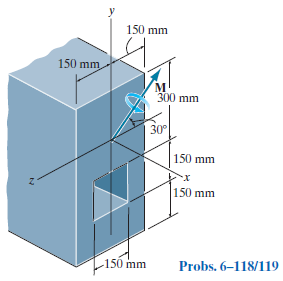

# section properties

% ------------------------------
% symbolic units class
u = symunit;
% ------------------------------
% y-axis centroid
yc = [300; 150+150/2]*u.mm;
Acz = [300*600; -150*150]*u.mm^2;
Icz = [300*600^3; -150*150^3]/sym(12)*u.mm^4;
[yn Qnz Inz] = beam.neutral_axis(yc, Acz, Icz); %#ok
Iz = sum(Inz);
% ------------------------------
% z-axis centroid
zc = [0; 0];
Acy = [600*300; -150*150]*u.mm^2;
Icy = [600*300^3; -150*150^3]/sym(12)*u.mm^4;
[zn Qny Iny] = beam.neutral_axis(zc, Acy, Icy); %#ok
Iy = sum(Iny);
% ------------------------------

# maximum bending stress

% ------------------------------
% bending moments
M = 1200*u.kN*u.m;
theta = 30*u.deg;
My = M*sin(theta);
Mz = -M*cos(theta);
% ------------------------------
% bending locations
y_max = [600*u.mm-yn; 600*u.mm-yn; -yn; -yn];
z_max = [150; -150; -150; 150]*u.mm;
% ------------------------------
% bending stress and neutral axis location
[sigma_max alpha] = beam.unsymmetric(My, Mz, Iy, Iz, y_max, z_max); %#ok
sigma_max = rewrite(sigma_max, u.MPa);
sigma_max_vpa = vpa(sigma_max, 5) %#ok

$$sigma\_max\_vpa = \left(\begin{array}{c} 126.49\,\mathrm{MPa}\\ -11.149\,\mathrm{MPa}\\ -130.76\,\mathrm{MPa}\\ 6.8772\,\mathrm{MPa} \end{array}\right)$$

alpha_vpa = vpa(alpha, 4) %#ok

$$alpha\_vpa = -66.51\,\deg$$

clear sigma_max_vpa alpha_vpa;
% ------------------------------